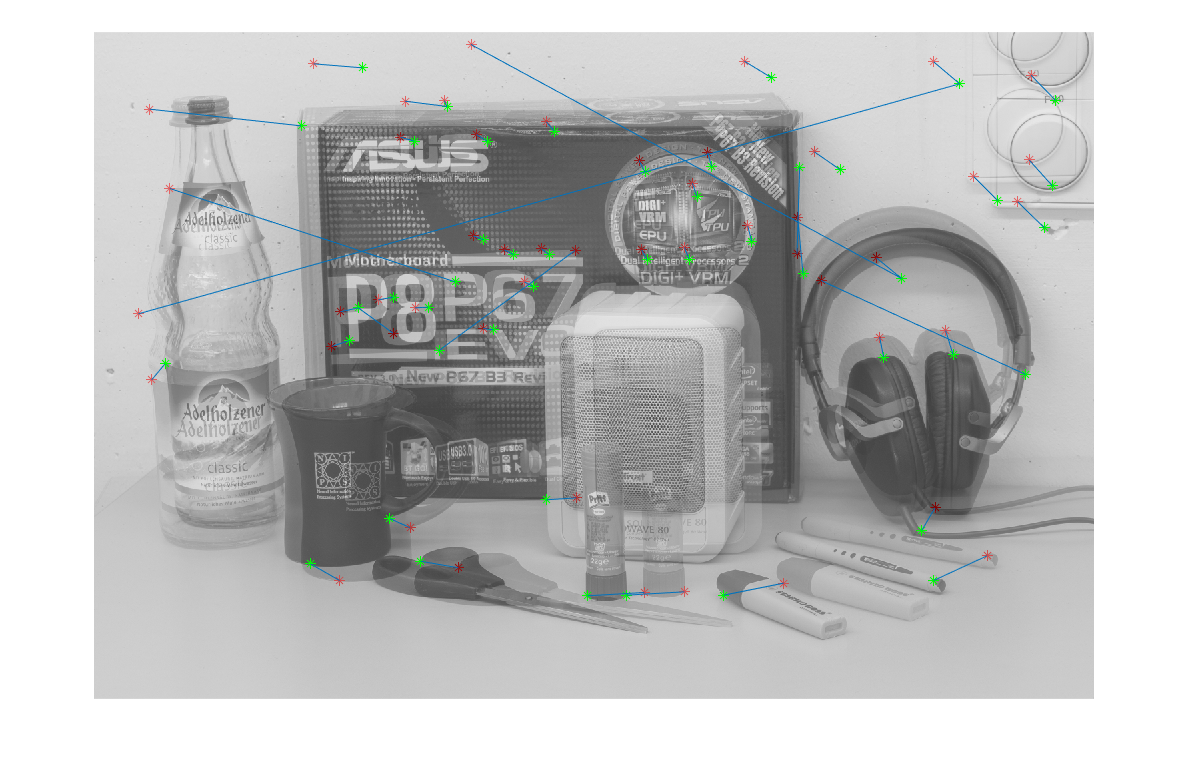

cor =          886         826         671         370         467         724         616         357         646         898         482        1179        1386         475         722         449        1406        1278         981         574         886        1174        1056         369         114         427        1260         460         921         679        1091         569          87        1320         822        1055        1403         584         526          67        1035        1340        1081          84        1262         330         818         566         547         976
         840         841         325         420         104         699         327         472         375         227         414         458         255         744         328         452          65         448         291         154         323         339         278         823         235         402          45         158         181         135         373         306         

% Bilder laden
Image1 = imread('sceneL.png');
IGray1 = rgb_to_gray(Image1);

Image2 = imread('sceneR.png');
IGray2 = rgb_to_gray(Image2);

% Harris-Merkmale berechnen
features1 = harris_detector(IGray1,'segment_length',9,'k',0.05,'min_dist',50,'N',20,'do_plot',false);
features2 = harris_detector(IGray2,'segment_length',9,'k',0.05,'min_dist',50,'N',20,'do_plot',false);

cor = point_correspondence(IGray1,IGray2,features1,features2,'window_length',25,'min_corr', 0.90,'do_plot',true)